clear;
clc;

%% Files to Matrixes
oldCube_WithScreenOverTable = readmatrix('OldCube_WithScreenOverTable.txt');
oldCube_NoScreenOverTable = readmatrix('OldCube_NoScreenOverTable.txt');
LucasCube_NoScreenOverTable = readmatrix('LucasCube_NoScreenOverTable.txt');
LucasCube_WithScreenOverTable = readmatrix('LucasCube_WithScreenOverTable.txt');
LucasCube_SideScreen = readmatrix('LucasCube_SideScreen.txt');
LucasCube_NoScreen2 = readmatrix('LucasCube_NoScreen2.txt');
LucasCube_GateScreen = readmatrix('LucasCube_GateScreen.txt');
LucasCube_GateScreen27p = readmatrix('LucasCube_GateScreen27p.txt');
LucasCube_GateScreen27pv2 = readmatrix('LucasCube_GateScreen27pv2.txt');

% EDIT HERE
csvFile1 = oldCube_WithScreenOverTable;
csvFile2 = LucasCube_GateScreen;
diagramtitel = "LucasCube_GateScreen27pv2";
sz = 15;

%% Creating data coloumns for each colored side.
gap1 = size(csvFile1, 1)/6 - 9;
dataY = csvFile1(1:9, :);
dataO = csvFile1(9+1+gap1:9*2+gap1, :);
dataG = csvFile1(9*2+1+gap1:9*3+gap1, :);
dataW = csvFile1(9*3+1+gap1:9*4+gap1, :);
dataR = csvFile1(9*4+1+gap1:9*5+gap1, :);
dataB = csvFile1(9*5+1+gap1:9*6+gap1, :);

gap2 = size(csvFile2, 1)/6 - 9;
dataY_2 = csvFile2(1:9, :);
dataO_2 = csvFile2(9+1+gap2:9*2+gap2, :);
dataG_2 = csvFile2(9*2+1+gap2:9*3+gap2, :);
dataW_2 = csvFile2(9*3+1+gap2:9*4+gap2, :);
dataR_2 = csvFile2(9*4+1+gap2:9*5+gap2, :);
dataB_2 = csvFile2(9*5+1+gap2:9*6+gap2, :);

figure;
hold on
% Scatter plot with circles
scatter(dataY(:,1),dataY(:,2), sz, ...
    'y', 'filled', 'MarkerEdgeColor',[0 0 0])
scatter(dataO(:,1),dataO(:,2), sz ...
    , [1 0.5 0], 'filled', 'MarkerEdgeColor',[0 0 0])
scatter(dataG(:,1),dataG(:,2), sz ...
    , 'g', 'filled', 'MarkerEdgeColor',[0 0 0])
scatter(dataR(:,1),dataR(:,2), sz ...
    , 'r', 'filled', 'MarkerEdgeColor',[0 0 0])
scatter(dataB(:,1),dataB(:,2), sz ...
    , 'b', 'filled', 'MarkerEdgeColor',[0 0 0])
scatter(dataW(:,1),dataW(:,2), sz ...
    , 'k', 'filled', 'MarkerEdgeColor',[0 0 0])

% Scatter plot with crosses
%{
%If you don't want 2 plots, move the percentage sign down to after these scatter plots
scatter(dataY_2(:,1), dataY(:,2), sz, ...
    'Marker', 'x', 'MarkerEdgeColor', 'y', 'LineWidth', 1.5)
scatter(dataO_2(:,1), dataO(:,2), sz, ...
    'Marker', 'x', 'MarkerEdgeColor', [1 0.5 0], 'LineWidth', 1.5)
scatter(dataG_2(:,1), dataG(:,2), sz, ...
    'Marker', 'x', 'MarkerEdgeColor', 'g', 'LineWidth', 1.5)
scatter(dataR_2(:,1), dataR(:,2), sz, ...
    'Marker', 'x', 'MarkerEdgeColor', 'r', 'LineWidth', 1.5)
scatter(dataB_2(:,1), dataB(:,2), sz, ...
    'Marker', 'x', 'MarkerEdgeColor', 'b', 'LineWidth', 1.5)
scatter(dataW_2(:,1), dataW(:,2), sz, ...
    'Marker', 'x', 'MarkerEdgeColor', 'k', 'LineWidth', 1.5)
%}

%% Boxes that capsulates the points
% Yellow cluster box
x = dataY(:,1); y = dataY(:,2);
rectangle('Position',[min(x)-4 min(y)-4 max(x)-min(x)+8 max(y)-min(y)+8], 'EdgeColor','y','LineWidth',1.5);
disp("Yellow")

Yellow


disp([min(x)-4 min(y)-4 min(x)+max(x)-min(x)+8 min(y)+max(y)-min(y)+8])

    37   148    50   186




% Orange cluster box
x = dataO(:,1); y = dataO(:,2);
rectangle('Position',[min(x)-4 min(y)-4 max(x)-min(x)+8 max(y)-min(y)+8], 'EdgeColor',[1 0.5 0],'LineWidth',1.5);
disp("Orange")

Orange


disp([min(x)-4 min(y)-4 min(x)+max(x)-min(x)+8 min(y)+max(y)-min(y)+8])

     1   177    17   212




% Green cluster box
x = dataG(:,1); y = dataG(:,2);
rectangle('Position',[min(x)-4 min(y)-4 max(x)-min(x)+8 max(y)-min(y)+8], 'EdgeColor','g','LineWidth',1.5);
disp("Green")

Green


disp([min(x)-4 min(y)-4 min(x)+max(x)-min(x)+8 min(y)+max(y)-min(y)+8])

    61   178    80   203




% Black cluster box
x = dataW(:,1); y = dataW(:,2);
rectangle('Position',[min(x)-4 min(y)-4 max(x)-min(x)+8 max(y)-min(y)+8], 'EdgeColor','k','LineWidth',1.5);
disp("White")

White


disp([min(x)-4 min(y)-4 min(x)+max(x)-min(x)+8 min(y)+max(y)-min(y)+8])

   100    75   116   105




% Red cluster box
x = dataR(:,1); y = dataR(:,2);
rectangle('Position',[min(x)-4 min(y)-4 max(x)-min(x)+8 max(y)-min(y)+8], 'EdgeColor','r','LineWidth',1.5);
disp("Red")

Red


disp([min(x)-4 min(y)-4 min(x)+max(x)-min(x)+8 min(y)+max(y)-min(y)+8])

    -2   197    15   257




% Blue cluster box
x = dataB(:,1); y = dataB(:,2);
rectangle('Position',[min(x)-4 min(y)-4 max(x)-min(x)+8 max(y)-min(y)+8], 'EdgeColor','b','LineWidth',1.5);
disp("Blue")

Blue


disp([min(x)-4 min(y)-4 min(x)+max(x)-min(x)+8 min(y)+max(y)-min(y)+8])

   106   230   119   253



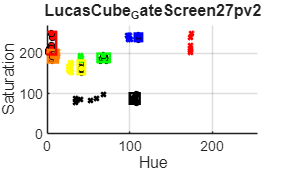


%% For the diagram
axis([0 255 0 270])
grid
xlabel("Hue")
ylabel("Saturation")
title(diagramtitel)
saveas(gcf, 'scatter_plot.png')